## MathTools HW1

%% 2024-9-13
%Question 1

## Tetsing

%a)Get projection of V onto U
u = [0;1];
v = [2;3];
question1a = projection(u,v);
disp('Returned vector for 1a:');

Returned vector for 1a:


disp(question1a);

     0
     3




%b)Get component V that is orthogonal to U
question1b = ortho(u,v); 
disp('Returned vector for 1b:');

Returned vector for 1b:


disp(question1b);

     2
     0




%c)Returns distance
question1c = distance(u,v);
disp('Returned distance:');

Returned distance:


disp(question1c);

     2



## Plotting 

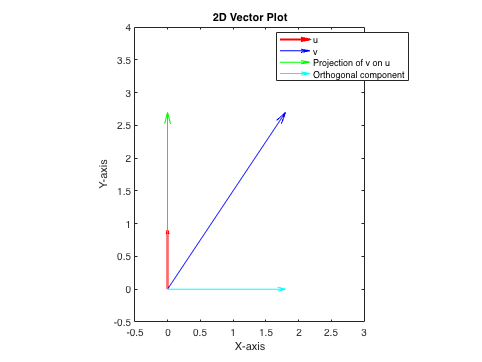

% figure;
% quiver(0, 0, u(1), u(2), 'r'); hold on; % Vector u
% quiver(0, 0, v(1), v(2), 'b');          % Vector v
% question1a = projection(u,v)
% quiver(0, 0, question1a(1), question1a(2), 'g');    % Projection of v onto u
% question1b = ortho(u,v)
% quiver(question1a(1), question1a(2), question1b(1), question1b(2), 'k');  % Orthogonal component
% axis equal;
% grid on;
% legend('u', 'v', 'Projection of v on u', 'Orthogonal component');

figure;
quiver(0, 0, u(1), u(2), 'r','LineWidth',2); hold on;% Vector u
quiver(0, 0, v(1), v(2), 'b'); hold on;% Vector v
quiver(0, 0, question1a(1), question1a(2), 'g'); hold on;% Projection
quiver(0, 0, question1b(1), question1b(2), 'c'); hold on;% Orthogonal
axis equal;
xlabel('X-axis'); ylabel('Y-axis');
title('2D Vector Plot');
xlim([-0.5, max(v(1)) + 1]); ylim([-0.5, max(v(2)) + 1]);
legend('u', 'v', 'Projection of v on u', 'Orthogonal component', Location='best');
hold off;

function question1a = projection(u,v)
question1a = (sum(v.*u)/sum(u.*u))*u; 
end 

function question1b = ortho(u,v)
question1a = projection(u,v);
question1b = v-question1a;
end 

function question1c = distance(u,v)
question1b = ortho(u,v);
question1c = sqrt(sum(question1b .^ 2));
end 
